## 레이더 제원 설정

레이더를 구성하는 안테나의 종류와 개수 그리고 배치 방식을 설정합니다.

8개의 코사인 안테나를 동일한 간격(ULA, Uniform Linear Array)으로 배치

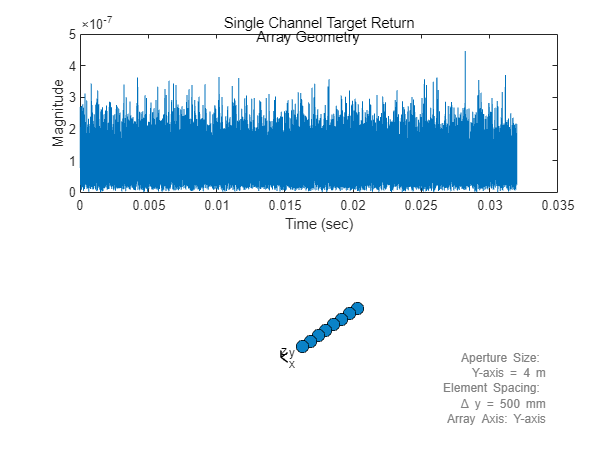

antenna=phased.ULA;
antenna.NumElements = 8;
cosineElement = phased.CosineAntennaElement;
antenna.Element = cosineElement;

viewArray(antenna);

레이더 제원에 따른 신호의 파형 시각화

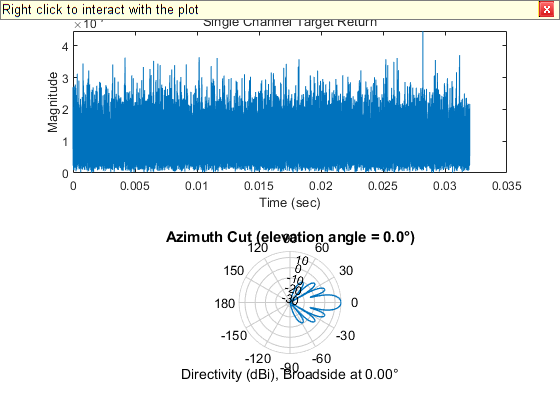

pattern(antenna,300e6,-180:180,0,...
    'Type','directivity',...
    'PropagationSpeed',3e8);

## 송신 펄스 설정

주파수 변조 방식, PRF, SampleRate 설정

Linear Frequency Modulation(선형 주파수 변조) 사용

초당 1,000번의 펄스 반복

초당 1,000,000번의 측정 > 펄스당 1,000개의 측정값 생성

prf = 1000;

waveform=phased.LinearFMWaveform;
waveform.SampleRate = 1e6;
waveform.PRF=prf;
waveform.PulseWidth=1e-4;

nSamples = waveform.SampleRate/waveform.PRF;
y = step(waveform);
t = (0:nSamples-1)/waveform.SampleRate;

송신 펄스(reference signal) 시각화

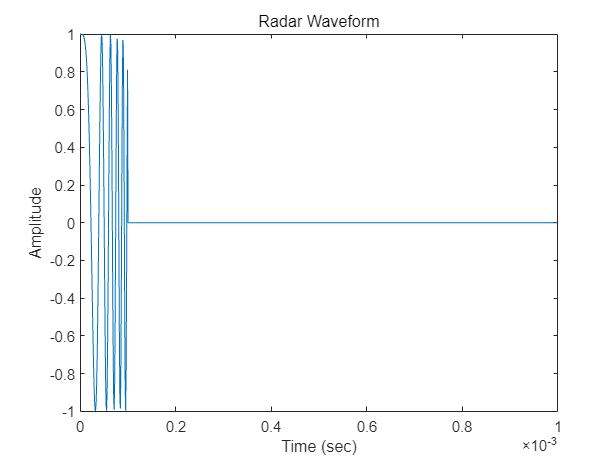

figure;
plot(t,real(y));title('Radar Waveform'); xlabel('Time (sec)'); ylabel('Amplitude')

## 송신부 설정

송신 신호 강도 설정

TX=phased.Transmitter('Gain',20);

## 타겟 설정

타겟의 좌표, 속도

타겟 = 목표 인스턴스, 플랫폼 = 시뮬레이션 인스턴스 (iterator 생성과 유사)

TgtModel=phased.RadarTarget;
tgtpos=[10e3*sqrt(3);10e3;0];  % Target at 20 km distance, 30 degree azimuth
tgtvel=[75*sqrt(3);75;0];      % Radial velocity is 150 m/sec

% Platform Specs
PlatformModel=phased.Platform;
PlatformModel.InitialPosition = tgtpos;
PlatformModel.Velocity = tgtvel;

임시, 타겟 움직임 저장

for ii=1:30000
   [tgtPos, tgtVel] = step(PlatformModel,1/prf);
   Poses(:,:,ii) = tgtPos;
   Vels(:,:,ii) = tgtVel;

end

임시, 타겟 움직임 시각화

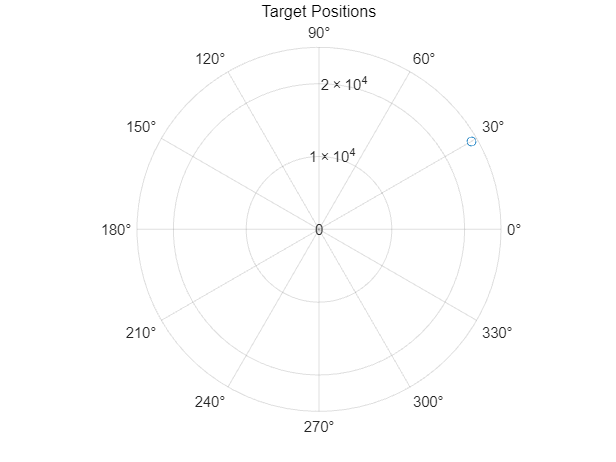

pos_idx = 28001;
pos = Poses(:,:,pos_idx);

figure;
[t,r]=(cart2pol(pos(1,:),pos(2,:),pos(3,:)));
polarplot(t,r,'o'); title('Target Positions')

## 채널 설정 (?)

아직은 잘 모르겠습니다..

channel이 antenna를 의미하는지? 알게된다면 수정 예정

ChannelModel = phased.FreeSpace;
ChannelModel.TwoWayPropagation=true;

## 송신 신호, 수신 신호 배열 생성

txArray = phased.Radiator(...
    'Sensor',antenna,...
    'OperatingFrequency',300e6);
rxArray = phased.Collector(...
    'Sensor',antenna,...
    'OperatingFrequency',300e6);
rxPreamp = phased.ReceiverPreamp('Gain',10,'NoiseFigure',5,...
    'SampleRate',1e6);

## 변수 정의

레이더 위치, 속도, 펄스 수, 데이터큐브 생성

정지된 레이더

32개의 펄스 관찰

0으로 초기화된 1000*8*32 형태의 데이터 큐브

radarPos = [0;0;0];
radarVel = [0;0;0];
nPulses = 32;

tgtAng = zeros(2,nPulses);
tgtAngcopy = zeros(2,nPulses);

datacube = complex(zeros(nSamples,antenna.NumElements,nPulses));

## 신호 생성 및 레코딩

"The radar data cube consists of the complex IQ data samples that are collected at the array for each pulse. The dimensions are 1000 time samples, by 8 receive elements, by 32 pulses (the number of pulses in our coherent processing interval for this example)."

위에서 생성한 모든 값 (waveform, target 등) 을 종합하여 datacube에 펄스단위로 데이터 생성/기록

for ii=1:nPulses
    wf=step(waveform);                                                 % Generate waveform
    [tgtPos, tgtVel] = step(PlatformModel,1/prf);                      % Update target position
    [tgtRng, tgtAng] = rangeangle(tgtPos, radarPos);                        % Calculate range/angle to target
    tgtAngcopy(:,ii)=tgtAng;
    s0 = step(TX, wf);                                                 % Amplify signal
    s1 = step(txArray,s0, tgtAng);                                     % Radiate the signal from the array
    s2 = step(ChannelModel, s0, radarPos, tgtPos, radarVel, tgtVel);   % Propagate from radar to target and return
    s3 = step(TgtModel, s2);                                           % Reflect signal from Target 
    s4 = step(rxArray,s3,tgtAng);                                      % Receive the signal at the array
    s5 = step(rxPreamp,s4);                                            % Add rx noise
    datacube(:,:,ii) = s5(:,:);                                            % Build data cube 1 pulse at a time

end

## 수신 신호 부분 시각화

antenna_idx : 안테나 인덱스 (1<=antenna_idx<=antenna.NumElements)

pulse_idx : 펄스 인덱스 (1<=pulse_idx<=num_pulse)

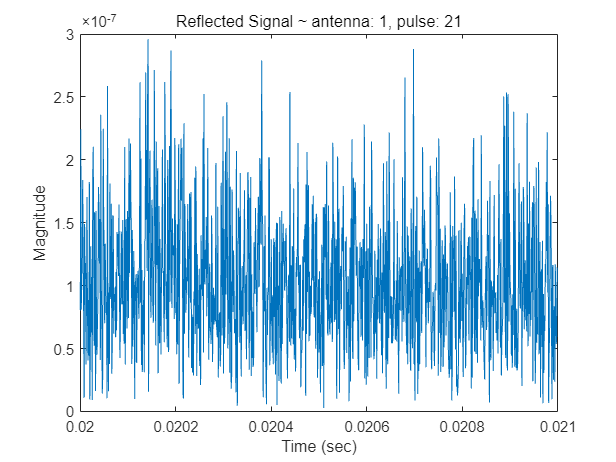

antenna_idx = 1;
pulse_idx =21;

t = ((pulse_idx-1)*nSamples:pulse_idx*nSamples-1)/waveform.SampleRate;
y = abs(datacube(:, antenna_idx, pulse_idx));

figure;
plot(t,y(:));
title(['Reflected Signal ~ antenna: ', num2str(antenna_idx),', ','pulse: ', num2str(pulse_idx)]);
xlabel('Time (sec)'); ylabel('Magnitude')

## 메모리 초기화 (답안 제거)

tgtAngcopy 삭제하기

clearvars -except antenna datacube waveform nPulses tgtAngcopy

nSamples = waveform.SampleRate/waveform.PRF;

## 빔포밍 (생략)

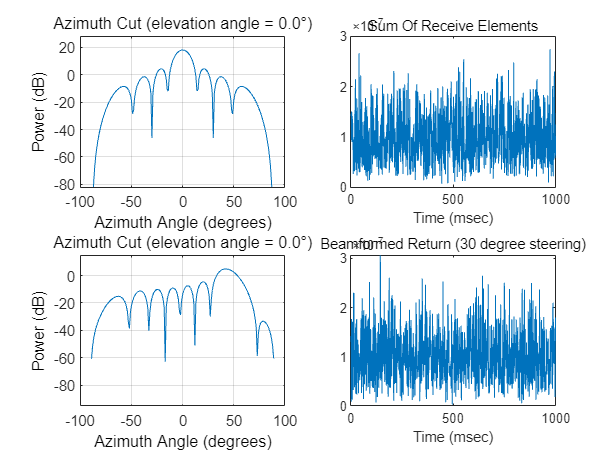

beamformer=phased.PhaseShiftBeamformer;
beamformer.SensorArray=antenna;
beamformer.DirectionSource='Input port';
beamformer.WeightsOutputPort=true;
beamformer.WeightsNormalization='Preserve power';


[bf0,w0]=step(beamformer,datacube(:,:,1),[0;0]);
[bf, w]=step(beamformer,datacube(:,:,1),[45;0]);

figure;
subplot(2,2,1);
pattern(antenna,300e6,-180:180,0,...
    'PropagationSpeed',physconst('LightSpeed'),'Normalize',false,...
    'Type','powerdb','CoordinateSystem','rectangular');
subplot(2,2,2);plot(abs(bf0));
title('Sum Of Receive Elements'); xlabel('Time (msec)');
subplot(2,2,3);pattern(antenna,300e6,-180:180,0,'Weights',w,...
    'PropagationSpeed',physconst('LightSpeed'),'Normalize',false,...
    'Type','powerdb','CoordinateSystem','rectangular');
subplot(2,2,4);plot(abs(bf)); 
title('Beamformed Return (30 degree steering)'); xlabel('Time (msec)');

빔포밍 수행

tgtAngcopy 대체하기 (직접 구하기)

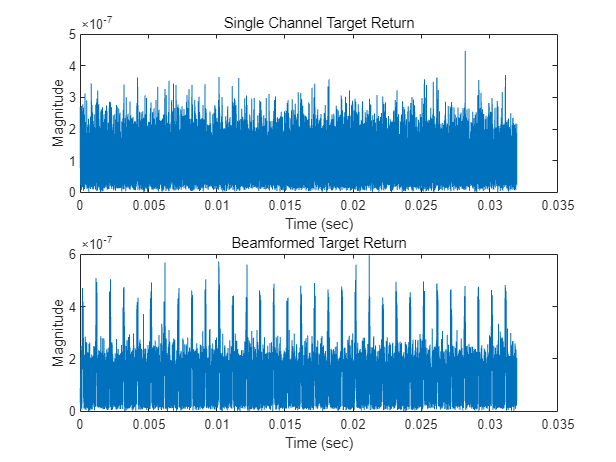

%% Beamform for all 32 pulses
beamformed=complex(zeros(nSamples,nPulses));
for ii=1:nPulses
    beamformed(:,ii)=step(beamformer,squeeze(datacube(:,:,ii)),tgtAngcopy(:,ii));
end
figure; 
t = (0:nPulses*nSamples-1)/waveform.SampleRate;
y = abs(reshape(beamformed,nPulses*nSamples,1));
dc=abs(reshape(datacube(:,1,:),nPulses*nSamples,1));
subplot(2,1,1);plot(t,dc);title('Single Channel Target Return'); xlabel('Time (sec)'); ylabel('Magnitude')
subplot(2,1,2);plot(t,y);title('Beamformed Target Return'); xlabel('Time (sec)'); ylabel('Magnitude')

## 펄스 압축

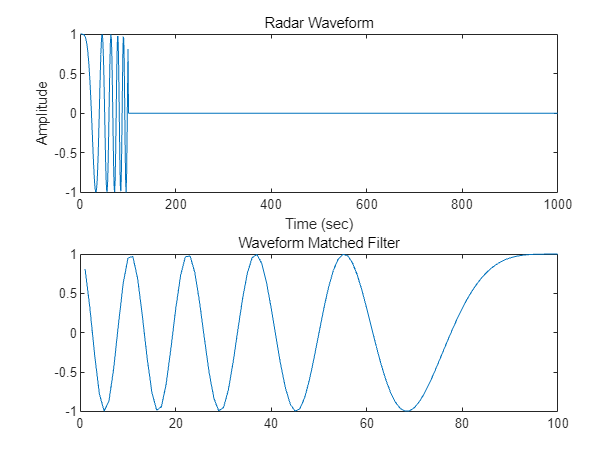

wf = waveform();

references = getMatchedFilter(waveform);
matchedfilter = phased.MatchedFilter(...
    'Coefficients',references,...
	'SpectrumWindow','Hamming');

matchFiltered = step(matchedfilter,datacube);

figure;
subplot(2,1,1);plot(real(wf));title('Radar Waveform'); xlabel('Time (sec)'); ylabel('Amplitude')
subplot(2,1,2);plot(real(references));title('Waveform Matched Filter');

d

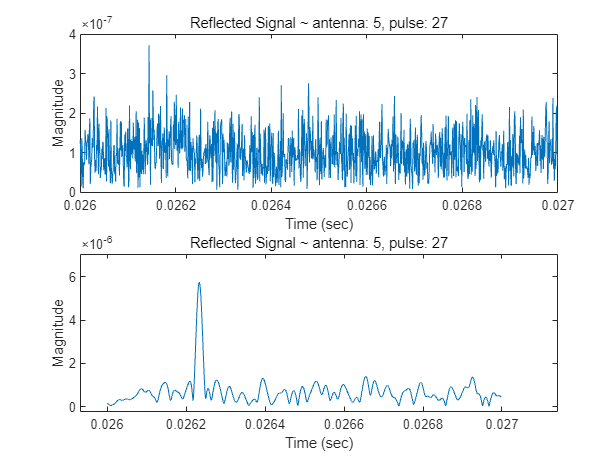

antenna_idx = 5;
pulse_idx =27;

t = ((pulse_idx-1)*nSamples:pulse_idx*nSamples-1)/waveform.SampleRate;
y = datacube(:, antenna_idx, pulse_idx);
filtered_y = matchFiltered(:, antenna_idx, pulse_idx);

figure;
subplot(2,1,1);plot(t,abs(y(:)));
title(['Reflected Signal ~ antenna: ', num2str(antenna_idx),', ','pulse: ', num2str(pulse_idx)]);
xlabel('Time (sec)'); ylabel('Magnitude')

subplot(2,1,2);plot(t,abs(filtered_y(:)));
title(['Reflected Signal ~ antenna: ', num2str(antenna_idx),', ','pulse: ', num2str(pulse_idx)]);
xlabel('Time (sec)'); ylabel('Magnitude')

거리 측정 (피크 반환 시간)

[m,ind] = max(abs(matchFiltered(:,antenna_idx,pulse_idx)));
targetRange = time2range((ind-length(references)-1)/waveform.SampleRate, beamformer.PropagationSpeed);

disp(['target distance: ', num2str(targetRange, '%.2f')])

target distance: 19936.20


속도 측정

dopplered = fftshift(fft(beamformed(ind,:).')); % Take the fft at the max amplitude range bin 
lambda=beamformer.PropagationSpeed/beamformer.OperatingFrequency;

h5 = figure;
f = (-prf/2:prf/nPulses:prf/2-prf/64);
v = f*lambda/2;
plot(v,abs(dopplered)); title('Doppler Processing'); xlabel('Target Speed (m/s)'); ylabel('Magnitude');
annotation(h5,'textbox',...
    [0.142657579062161 0.836671802773498 0.151671755725191 0.0647149460708782],...
    'String',strcat('Range = ',num2str(targetRange),'m'),...
    'FitBoxToText','on');

d

figure;
rangeDoppler=phased.RangeDopplerResponse;
rangeDoppler.DopplerOutput='Speed';
plotResponse(rangeDoppler,beamformed,b)
ylabel('Range (km)');